opts = optimoptions(@fmincon,'Display','iter','Algorithm','sqp');
opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');

Gk = tf([0,2],[1,2,2])

Gk =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    4.515151e+00     2.115e-07     1.000e+00     0.000e+00     1.337e+01  
    1          16    4.050732e+00     2.079e-07     5.765e-02     5.666e-01     2.043e+01  
    2          26    2.474173e+00     2.006e-07     1.176e-01     6.652e-01     8.735e+00  
    3          35    2.312532e+00     1.971e-07     1.681e-01     4.183e-01     3.410e+00  
    4          39    4.504039e-01     2.037e-07     1.000e+00     6.627e-01     5.399e-01  
    5          47    6.573490e+00     1.905e-07     2.401e-01     1.435e+00     5.700e+00  
    6          51    3.176958e+00     1.948e-07     1.000e+00     5.741e-01     4.975e+00  
    7          60    1.426048e+00     1.983e-07     1.681e-01     3.920e-01     3.940e+00  
    8          72    3.374330e+00     1.944e-07     5.765e-02     4.249e-01     5.

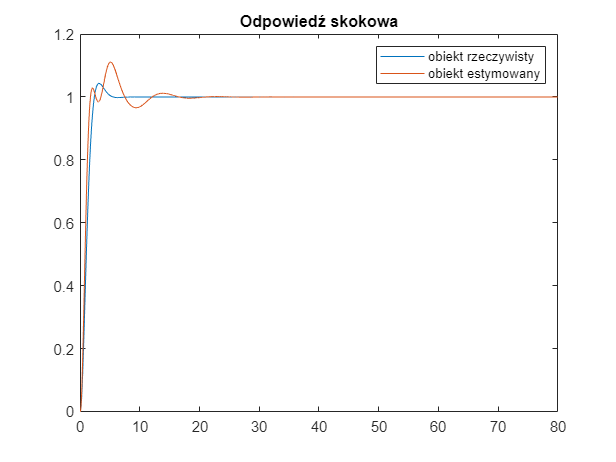

   12         128    6.358309e+00     1.905e-07     9.095e-07     2.630e-06     6.488e+00  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.3307    1.9840    2.6876


fun2 = @PID;
nonlinfcn2 = @Hurwitz2;
%ograniczenia na nastawy
lb = [0.2,0.2,0.2];
ub = [5,10,10];

%warunek początkowy
x0 = [1,1,1];

x = fmincon(fun2,x0,[],[],[],[],lb,ub,nonlinfcn2,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    6.201388e+01     1.678e-07     1.000e+00     0.000e+00     4.450e+00  
    1           9    5.004821e+01     1.681e-07     7.000e-01     3.210e+00     3.148e+02  
    2          13    4.063722e+01     1.715e-07     1.000e+00     5.405e+00     3.174e+02  
    3          17    2.078611e+01     1.822e-07     1.000e+00     3.472e+00     3.188e+02  
    4          23    1.461919e+01     1.958e-07     4.900e-01     1.853e+00     3.267e+02  
    5          28    6.864787e+00     2.008e-07     7.000e-01     1.542e+00     3.269e+02  
    6          37    7.196777e+00     1.909e-07     1.681e-01     1.053e+00     2.635e+02  
    7          43    4.204750e+00     1.989e-07     4.900e-01     1.210e+00     2.640e+02  
    8          53    7.779472e+00     1.915e-07     1.176e-01     8.022e-01     2.

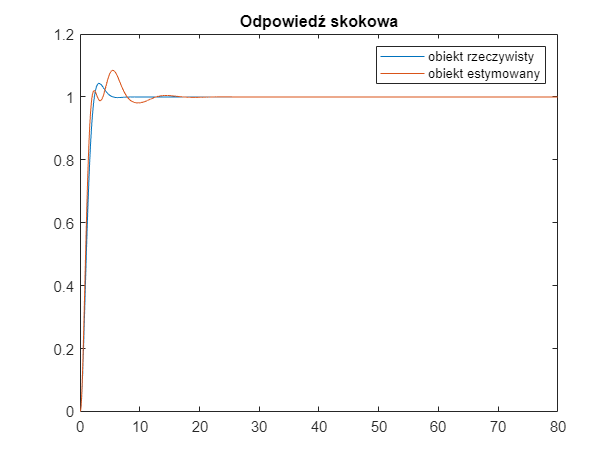

   23         179    2.881925e+00     1.952e-07     9.095e-07     1.888e-06     5.902e+00  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.3408    1.6371    2.1775


x0 = [4,9,9];

x = fmincon(fun2,x0,[],[],[],[],lb,ub,nonlinfcn2,opts)

C = pid(x(1),x(2),x(3)) 

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.34, Ki = 1.64, Kd = 2.18
 
Continuous-time PID controller in parallel form.



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    2.310266e+02     2.316e-07     1.000e+00     0.000e+00     1.301e+03  
    1          13    8.677835e+01     2.145e-07     1.681e-01     1.947e+00     5.778e+02  
    2          17    5.824396e+01     1.663e-07     1.000e+00     1.010e+01     2.175e+02  
    3          21    5.625507e+01     1.663e-07     1.000e+00     5.219e-01     2.174e+02  
    4          25    4.905742e+01     1.663e-07     1.000e+00     2.492e+00     2.165e+02  
    5          30    4.863117e+01     1.672e-07     7.000e-01     1.380e+00     2.155e+02  
    6          34    4.231382e+01     1.689e-07     1.000e+00     1.316e+00     2.157e+02  
    7          39    1.613833e+01     1.882e-07     7.000e-01     5.617e+00     2.134e+02  
    8          45    1.478471e+01     2.016e-07     4.900e-01     1.420e+00     2.

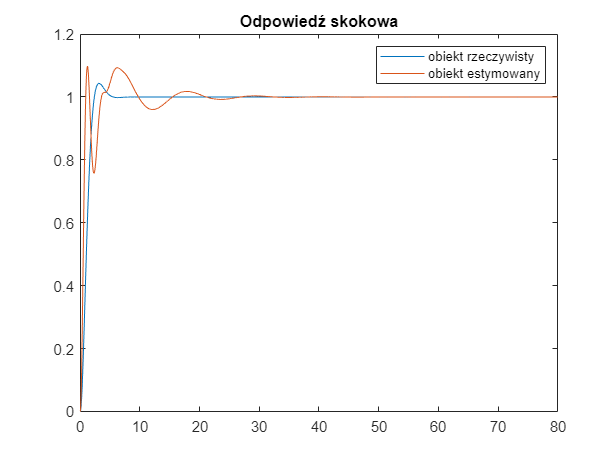

   16         153    3.229528e+01     1.734e-07     1.856e-06     5.471e-06     6.132e+00  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.5138    2.5053    6.2856


x0 = [0.2,0.2,0.2];

x = fmincon(fun2,x0,[],[],[],[],lb,ub,nonlinfcn2,opts)

C = pid(x(1),x(2),x(3)) 

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.51, Ki = 2.51, Kd = 6.29
 
Continuous-time PID controller in parallel form.



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    6.869544e+01     1.663e-07     1.000e+00     0.000e+00     4.179e+00  
    1           8    5.809240e+01     1.663e-07     1.000e+00     4.698e+00     4.226e+02  
    2          12    5.430052e+01     1.663e-07     1.000e+00     3.437e+00     4.215e+02  
    3          16    4.417689e+01     1.695e-07     1.000e+00     3.772e+00     4.220e+02  
    4          21    3.178430e+01     1.812e-07     7.000e-01     4.199e+00     4.263e+02  
    5          26    8.405797e-01     2.049e-07     7.000e-01     2.944e+00     4.154e+02  
    6          41    8.050350e-01     2.027e-07     1.977e-02     1.670e-01     4.177e+02  
    7          49    5.799111e-01     2.039e-07     2.401e-01     2.162e-01     4.205e+02  
    8          56    1.035970e+01     1.869e-07     3.430e-01     2.004e+00     2.

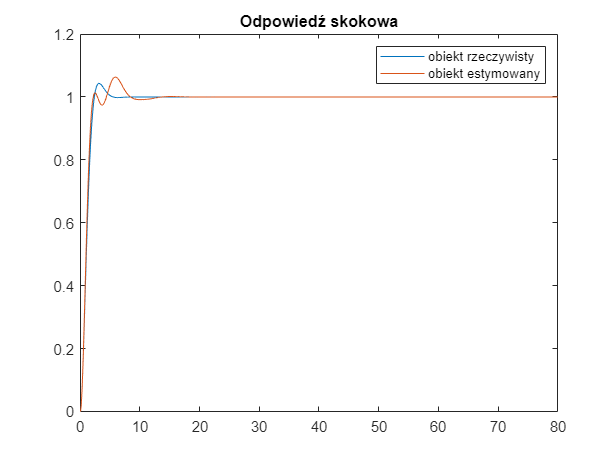

   11         104    1.487285e+00     1.987e-07     1.856e-06     1.773e-06     5.319e+00  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.3628    1.3978    1.8599


x0 = [5,10,10];

x = fmincon(fun2,x0,[],[],[],[],lb,ub,nonlinfcn2,opts)

C = pid(x(1),x(2),x(3)) 

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.36, Ki = 1.4, Kd = 1.86
 
Continuous-time PID controller in parallel form.



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    4.159605e+01     1.695e-07     1.000e+00     0.000e+00     4.088e+00  
    1           9    2.912408e+01     1.771e-07     7.000e-01     3.179e+00     2.908e+02  
    2          13    2.706140e+01     2.316e-07     1.000e+00     5.640e+00     3.061e+02  
    3          20    2.323274e+01     2.029e-07     3.430e-01     1.713e+00     1.934e+02  
    4          29    1.695236e+01     1.884e-07     1.681e-01     2.069e+00     1.995e+02  
    5          34    8.376998e+00     1.907e-07     7.000e-01     1.696e+00     1.908e+02  
    6          38    5.860900e+00     1.925e-07     1.000e+00     8.259e-01     1.940e+02  
    7          42    2.656600e+00     1.964e-07     1.000e+00     4.629e-01     1.918e+02  
    8          47    1.720083e+00     2.081e-07     7.000e-01     9.973e-01     1.

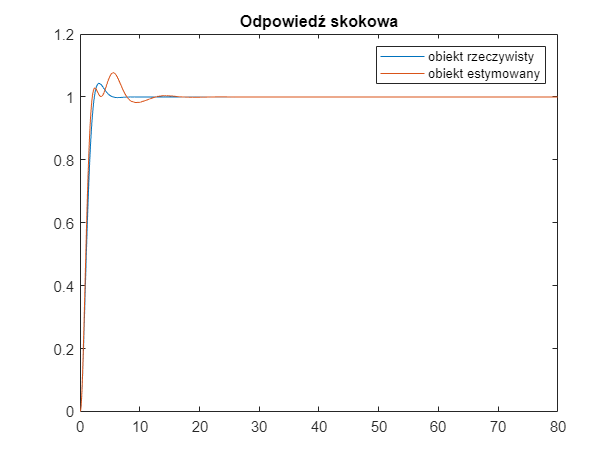

   16         122    2.042273e+00     1.968e-07     1.856e-06     2.197e-06     4.946e+00  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     1.3266    1.5839    2.0233


x0 = [2,4,8];
 
x = fmincon(fun2,x0,[],[],[],[],lb,ub,nonlinfcn2,opts)

C = pid(x(1),x(2),x(3))    % optymalizowany Controller

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.33, Ki = 1.58, Kd = 2.02
 
Continuous-time PID controller in parallel form.



function [c,ceq] = Hurwitz2(xk)

G1=tf([0 1],[1 2 2.25 1.25]); % obiekt sterowania
C = pid(xk(1),xk(2),xk(3))  ;    % optymalizowany Controller
G2 = series(C,G1);
G2 = feedback(G2,1);
x = G2.Denominator{1,1};



%Kryt Hurwitza
H=[x(2) 0;x(1) x(3)]; %macierz Hurwitza
H1=H(1,1);
H2=H(1:2,1:2);
a1=x(3);
a2=x(2);
a3=x(1);
Det_H1=det(H1);
Det_H2=det(H2);
Det_H=det(H);

mian_p=0.0000001; % wsp korygujacy NaN dzielenie przez zero;
c5=abs(Det_H2)/(Det_H2+mian_p);
c6=abs(Det_H)/(Det_H+mian_p);


a1_abs=abs(x(3))/(x(3)+mian_p);
a2_abs=abs(x(2))/(x(2)+mian_p);
a3_abs=abs(x(1))/(x(1)+mian_p);

c(1) = -x(1);
c(2) = -x(2);
c(3) = -x(3);
%c(5) = c5 - 1;
%c(6) = c6 - 1;

c(5) = -Det_H2;
c(6) = -Det_H;

%c = []; % wylaczenie  nierownosci
ceq=a1_abs+a2_abs+a3_abs+c5+c6-5;
end




function blad = PID(x)
%K = X0(1);
%T = X0(2);
%n = X0(3);

%a1=x(1);
%b2=x(2);

t=0:0.01:80;

%transmitancja Gk
Gk = tf([0,2],[1,2,2]);

%nasza transmitancja z dopasowaniem
G1=tf([0 1],[1 2 2.25 1.25]); % obiekt sterowania
C = pid(x(1),x(2),x(3));      % optymalizowany Controller
G2 = series(C,G1);
G2 = feedback(G2,1);


[y1] = step(Gk,t); % wzor
[y2] = step(G2,t); % dopasowanie



%---------------------------------------- ------%
% tutaj kod, który będzie obliczał
% odpowiedź skokową estymowanego modelu z optymalizacji
% o takiej samej długości jak odpowiedź
% obiektu rzeczywistego
plot(t, y1);
hold on;
plot(t, y2);
hold off;
legend(["obiekt rzeczywisty", "obiekt estymowany"])
title("Odpowiedź skokowa")


%---------------------------------------- ------%
e = y1-y2;
blad= sum(e.^2);
%blad= sum(e.^2) / length(e);
end
